Start Plotting...

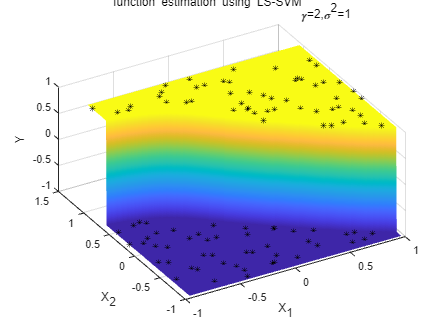

finished


%% load 数据
close all;clear;clc;
X = 2.*rand(100,2)-1;
Y = sign(sin(X(:,1))+X(:,2));
 
type = 'f';
L_fold = 10; % L-fold crossvalidation
 
%% 获得对象接口
model = initlssvm(X,Y,'f',2,1,'RBF_kernel');
 
%% 参数寻优
%model = tunelssvm(model,'simplex','crossvalidatelssvm',{L_fold,'misclass'});
%model = tunelssvm(model);
 
%% 模型训练和图形化显示 
model = trainlssvm(model);
plotlssvm(model);

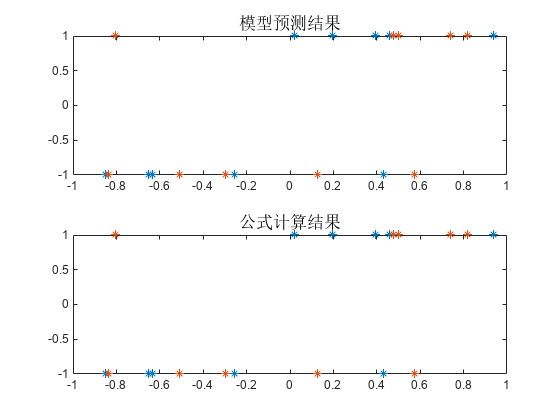

 
%% 利用训练模型进行预测
Xt = 2.*rand(10,2)-1;
Ytest = simlssvm(model,Xt);
 
%% 利用公式计算真实值，并与模型预测结果进行对比
YY = sign(sin(Xt(:,1))+Xt(:,2));
figure
subplot(2,1,1)
plot(Xt,Ytest,'*'); title('模型预测结果','fontsize',13); 
subplot(2,1,2)
plot(Xt,YY,'*'); title('公式计算结果','fontsize',13); 

 
ypred = length(find(Ytest==YY))/(length(Ytest)) * 100;
disp(['accuracy = ' ,num2str(ypred),'%'])

accuracy = 100%


 
%% ROC曲线
% latent variables are needed to make the ROC curve
Y_latent = latentlssvm(model,X);

错误使用 latentlssvm
Only usefull for classification tasks...

[area,se,thresholds,oneMinusSpec,Sens]=roc(Y_latent,Y);
[thresholds oneMinusSpec Sens];